# Wavelets Daubechies

Los coeficientes de las Wavelets Daubechies se obtienen a mano. Lo que se busca estos cumplen las siguientes propiedades. 


$$\sum_k a_k =2$$



$$\sum_k a_k^2 =2$$



$$\sum_k {\left(-1\right)}^k a_k k^l =0$$


En la última ecuación l va desde 0 a N/2 - 1 Donde N es el número de coeficientes.  Así, lo que esencialmente hacemos es plantear un sistema de ecuaciones con estas propiedades y resolvemos para los coeficientes. Una vez obtenidos podemos obtener los valores de la función de escalamiento en enteros $\phi \;\left(0\right)$, $\phi \left(1\right),\ldotp \ldotp \ldotp \ldotp \ldotp ,\phi \left(N-1\right)$, resolviendo el siguiente problema de Eigenvalores. 


$$\left\lbrack \begin{array}{ccccccc}
a_0  & 0 & 0 & \cdots \; & 0 & 0 & 0\\
a_2  & a_1  & a_0  & \cdots \; & 0 & 0 & 0\\
a_4  & a_3  & a_2  & \cdots \; & 0 & 0 & 0\\
\cdots \; & \cdots \; & \cdots \; & \cdots \; & \cdots \;\; & \cdots \; & \cdots \;\\
0 & 0 & 0 & \cdots \; & a_{N-3}  & a_{N-4}  & a_{N-5} \\
0 & 0 & 0 & \cdots \; & a_{N-1}  & a_{N-2}  & a_{N-3} \\
0 & 0 & 0 & \cdots \; & 0 & 0 & a_{N-1} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\phi \left(0\right)\\
\phi \left(1\right)\\
\phi \left(2\right)\\
\cdots \;\\
\phi \left(N-3\right)\\
\phi \left(N-2\right)\\
\phi \left(N-1\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\phi \left(0\right)\\
\phi \left(1\right)\\
\phi \left(2\right)\\
\cdots \;\\
\phi \left(N-3\right)\\
\phi \left(N-2\right)\\
\phi \left(N-1\right)
\end{array}\right\rbrack$$


Es decir, explicitamente lo que haríamos es construir esta matriz, con los coeficientes que ya tenemos, y obtener el eigenvector que corresponde al eigenvalor 1. Dicho eigenvector contiene los valores de la función de escalamiento en los números enteros. 

Para obtener mas granularidad podemos ir calculando la función de escalamiento en x/2 mediante la siguiente relación:


$$\phi \left(\frac{x}{2}\right)=\sum_k a_k \phi \left(x-k\right)$$


Una vez que tenemos la función de escalamiento, podremos hayar facilmente la wavelet por medio de la siguiente ecuación 


$$\psi \left(x\right)=\sum_k {\left(-1\right)}^k a_{n-1-k} \phi \left(2\;x-k\right)$$


Calculemos .los coeficientes para N = 1, 2, 3, 4 y dibujemos las ondas !

## N = 1 (Haar)

Aquí solo tendriamos dos coeficientes $a_0$ y $a_1$.

Nuestro sistema de ecuaciones es 


$$\begin{array}{l}
a_0 +a_1 =2\\
a_0^2 +a_1^2 =2\\
a_0 -a_1 =0
\end{array}$$


De la tercera ecuación obtenemos $a_0 =a_1$ y sustituyendo en la primera queda:


$$a_0 =1=a_1$$


Así que en este caso ambos coeficientes son iguales. 

La matriz a analizar para obtener los valores de la función de escalamiento en este caso es:

$\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$ voy a hacer de hecho una función que me automatice esta última parte del proceso  (vease WaveletBuilder). 

%Creamos el constructor de Wavelets implementado
waveletBuilder = WaveletBuilder();
coeffs = [1,1];
[tArray, scalingFunction, wavelet] = waveletBuilder.getDaubechiesWaveletWithCoeffs(coeffs, 854);

     0



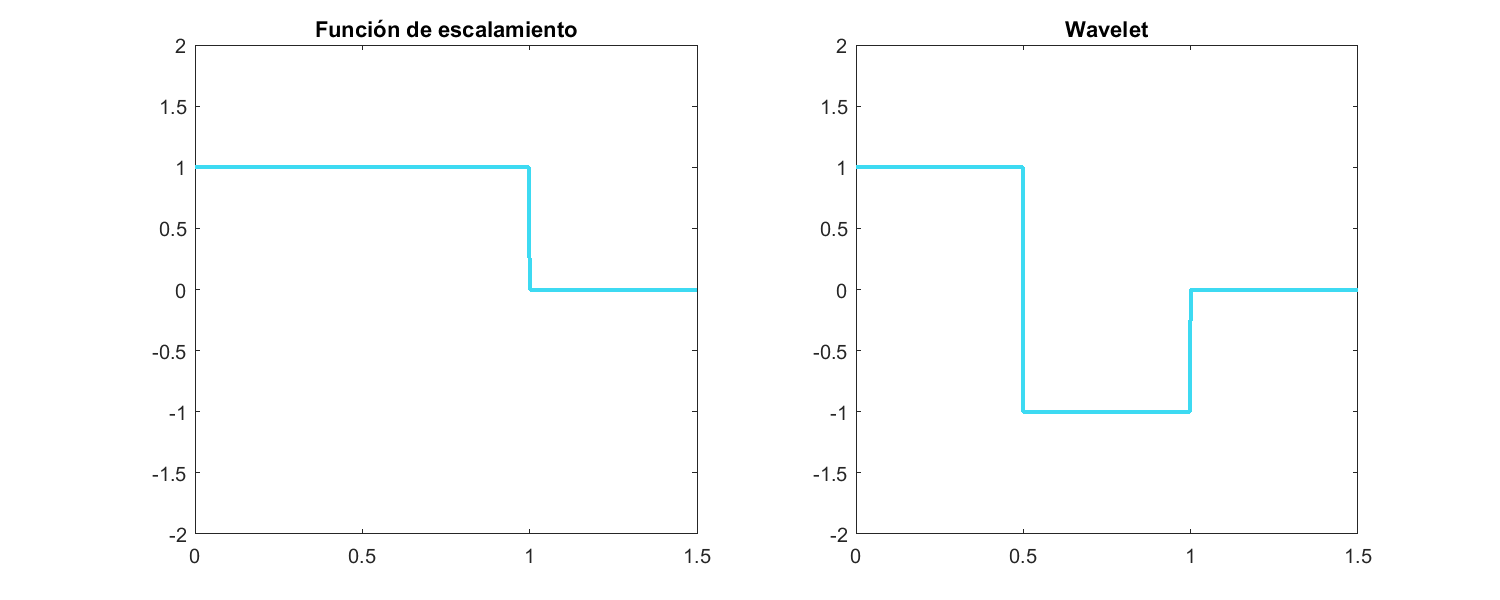


figure()
figure('Renderer', 'painters', 'Position', [10 10 1000 400])
subplot(1,2,1)
plot(tArray, scalingFunction, "Color", "#3ddaf2", "LineWidth", 2)
title("Función de escalamiento")
ylim([-2,2])
xlim([0,1.5])
subplot(1,2,2)
plot(tArray, wavelet, "Color", "#3ddaf2", "LineWidth", 2)
title("Wavelet")
ylim([-2,2])
xlim([0,1.5])

## Daubechies - 4


$$\begin{array}{l}
a_0 +a_{1\;} +a_2 \;+a_3 =2\\
a_0^2 +a_1^{2\;} +a_2^2 \;+a_3^2 =2\\
a_0 -a_1 +a_2 -a_3 =0\\
-a_1 +2a_2 \;-\;3a_3 =0
\end{array}$$
 

Sin ahondar demasiado en los detalles, las soluciones de esto son:


$$a_0 =\frac{1+\sqrt{3\;}}{4}\;\;\;\;\;a_1 =\frac{3+\sqrt{3\;}}{4}\;\;\;\;\;\;a_2 =\frac{3-\sqrt{3}}{4}\;\;\;a_3 =\frac{1-\sqrt{3}}{4}$$


Introduczcamos esto en nuestra función a ver que obtenemos

coeffs = [(1 + sqrt(3))/4, (3 + sqrt(3))/4,  (3 - sqrt(3))/4, (1 - sqrt(3))/4 ];
[tArray, scalingFunction, wavelet] = waveletBuilder.getDaubechiesWaveletWithCoeffs(coeffs,854);

   1.1102e-16



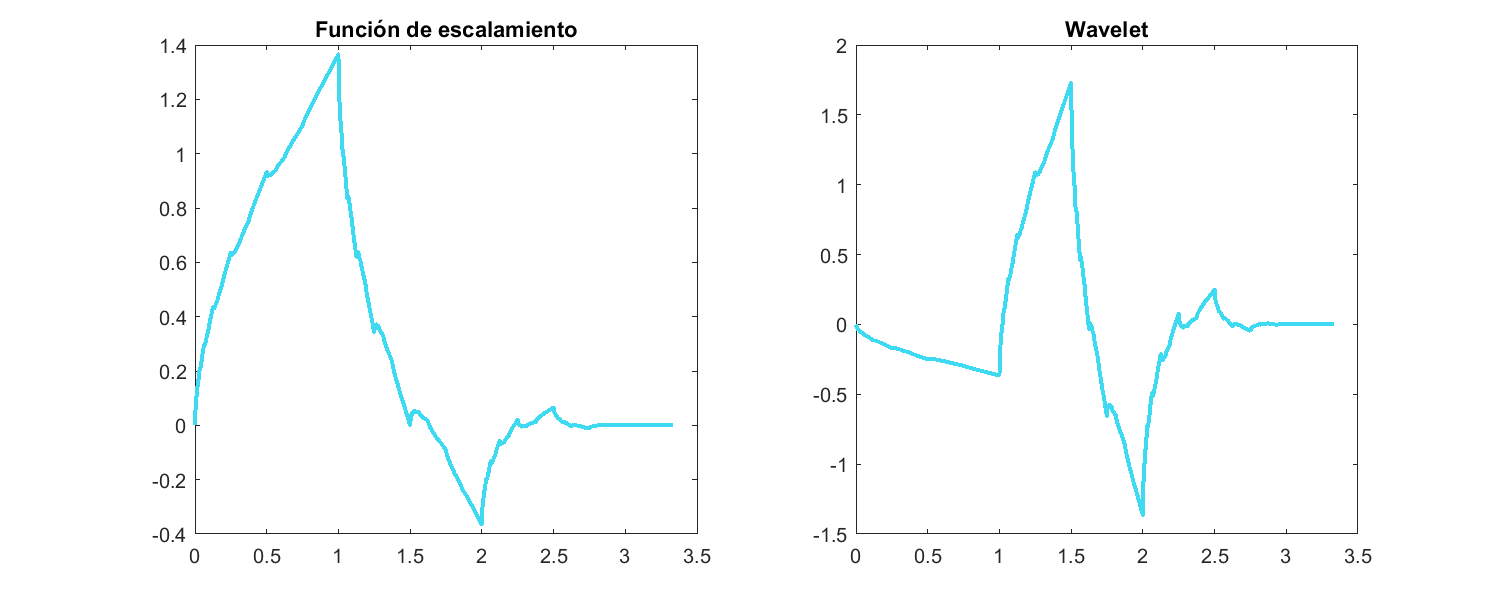


figure()
figure('Renderer', 'painters', 'Position', [10 10 1000 400])
subplot(1,2,1)
plot(tArray, scalingFunction, "Color", "#3ddaf2", "LineWidth", 2)
title("Función de escalamiento")
subplot(1,2,2)
plot(tArray, wavelet, "Color", "#3ddaf2", "LineWidth", 2)
title("Wavelet")

## CWT (Continuous wavelet transform)

La implementación de esta se hace siguiendo la definición de la transformada Wavelet como tal, es decir hay que ir haciendo la correlación de la señal con la Wavelet madre a distintos escalamientos de la Wavelet madre. Aquí algo importante fue hacer una función que nos fuese trasladando y escalando las ondas. Vamos a probar. 

%Escalamiento de las ondas 

wb = WaveletBuilder();
[tArray, wavelet] = wb.getWavelet(WaveletType.DAUBECHIES_4, 100);

   1.1102e-16



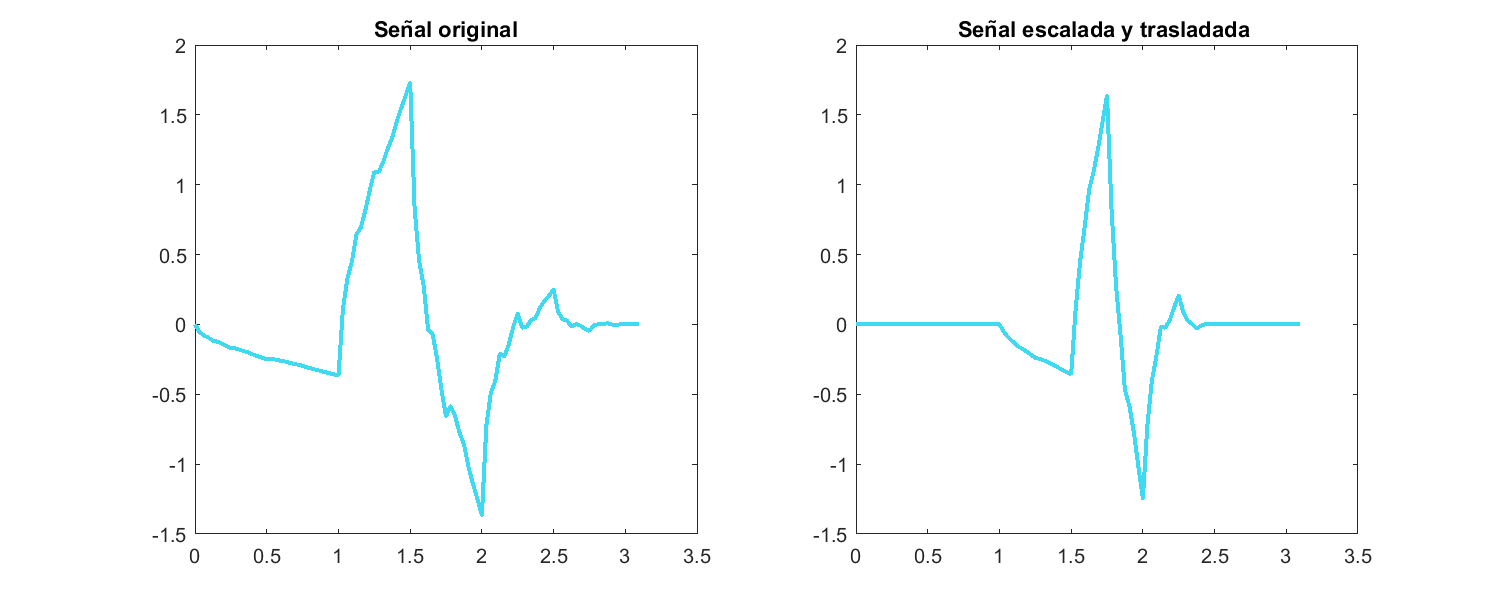

[newT, translatedWavelet] = wb.translateAndScale(wavelet, 1, 0.5, tArray);

figure()
figure('Renderer', 'painters', 'Position', [10 10 1000 400])
subplot(1,2,1)
plot(tArray, wavelet,"Color", "#3ddaf2", "LineWidth", 2)
title("Señal original")
subplot(1,2,2)
plot(tArray, translatedWavelet, "Color", "#3ddaf2", "Linewidth", 2)
title("Señal escalada y trasladada ")

Construyamos una señal para poder analizarla con CWT 

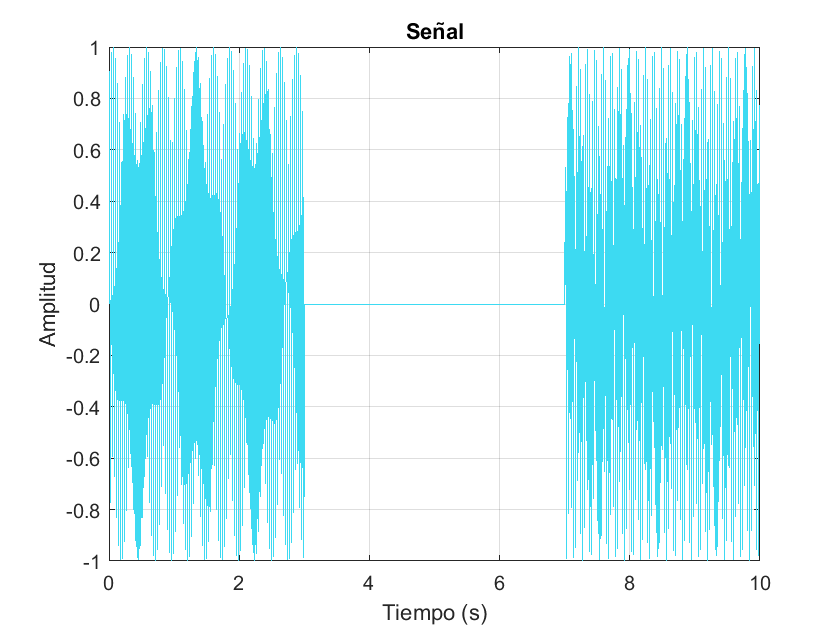

freq1 = 32;
amp1 = 1;
freq2 = 64;
amp2 = 1;
tArray = linspace(0,10,1000);
signal = amp1*sin(2*pi*freq1*tArray).*(tArray>=0 & tArray<3)+amp2*sin(2*pi*freq2*tArray).*(tArray>7 & tArray<10);

figure()
plot(tArray,signal, "Color", "#3ddaf2")
grid on
xlabel('Tiempo (s)')
ylabel('Amplitud')
title('Señal')

#### CWT con HAAR

continuousTransformer = ContinuousWaveletTransform();

[sArray, tArray, continuousTransform] = continuousTransformer.computeContinuousTransform(signal, tArray, 0.005, 0.1, 1000,WaveletType.DAUBECHIES_1);

     0



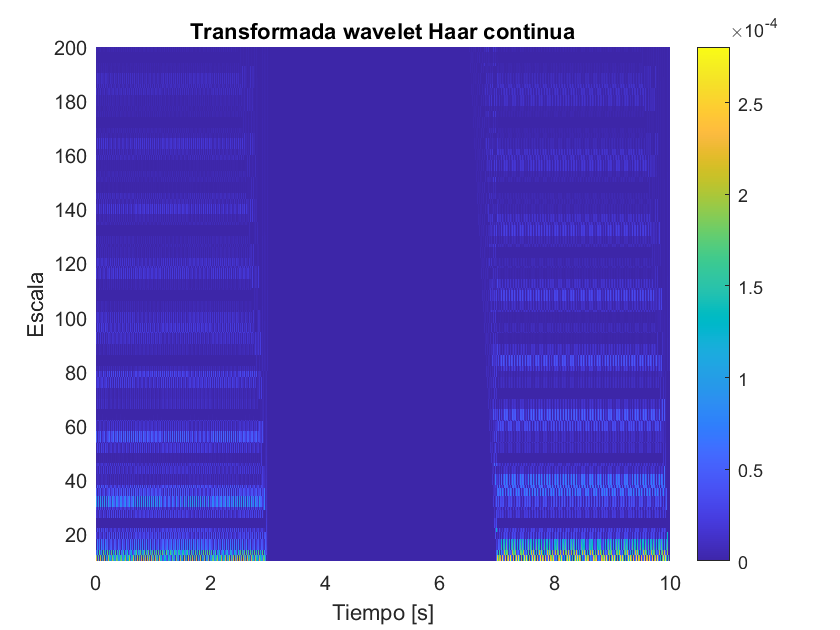


figure()
hold on 
imagesc(tArray, flip(1./sArray), continuousTransform)
set(gca,'YDir','normal');
title("Transformada wavelet Haar continua")
colorbar
xlabel("Tiempo [s]")
ylabel("Escala")
ylim([10,200])
xlim([0,10])
hold off

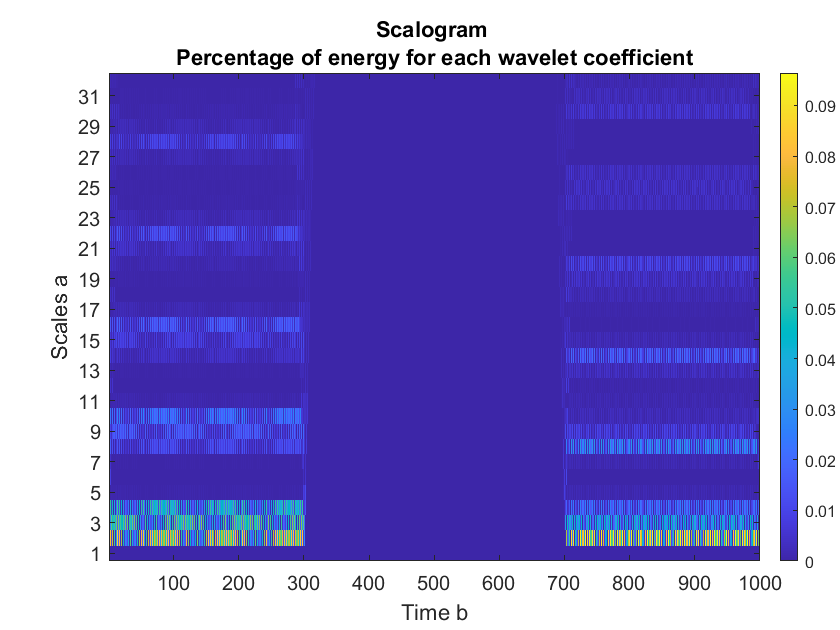

% Comparación con la función de MATLAB
coefs = cwt(signal,1:32,'db1');


% Compute and plot the scalogram (image option)
figure;
SC = wscalogram('image',coefs);

### CWT con Daubechies

continuousTransformer = ContinuousWaveletTransform();

[sArray, tArray, continuousTransform] = continuousTransformer.computeContinuousTransform(signal, tArray, 0.005, 0.1, 1000,WaveletType.DAUBECHIES_4);

   1.1102e-16



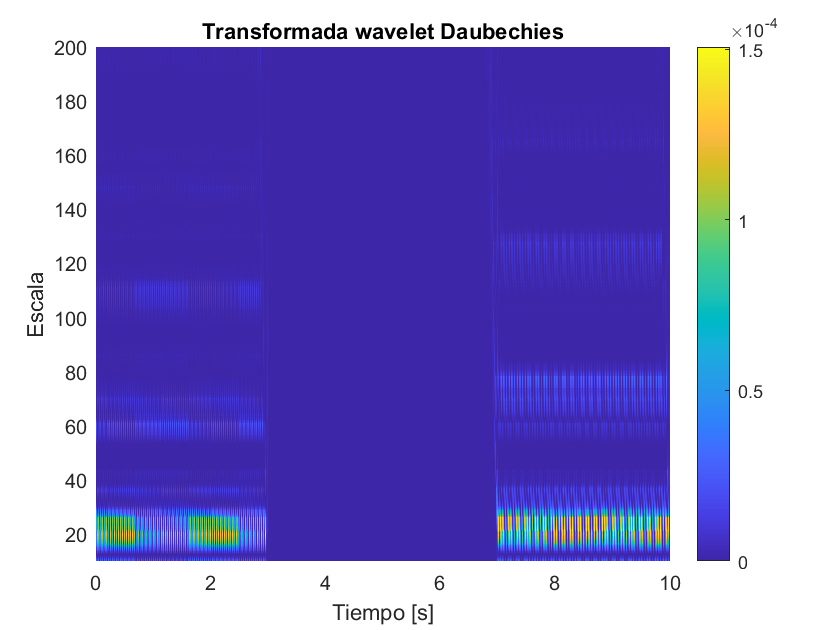


figure()
hold on 
imagesc(tArray, flip(1./sArray), continuousTransform)
set(gca,'YDir','normal');
title("Transformada wavelet Daubechies")
colorbar
xlabel("Tiempo [s]")
ylabel("Escala")
ylim([10,200])
xlim([0,10])
hold off

## DWT (Discrete Wavelet Transform)

La transformada discreta se implementa con filtros, tal y como vimos en clase. Aquí hice una función que me regresara los filtros, tanto para hacer la descomposición, como para hacer la reconstrucción. Lo que hago es simplemente usar la función que ya se había implementado en sesiones anteriores para filtrar con FIR e IIR. 

### Con HAAR

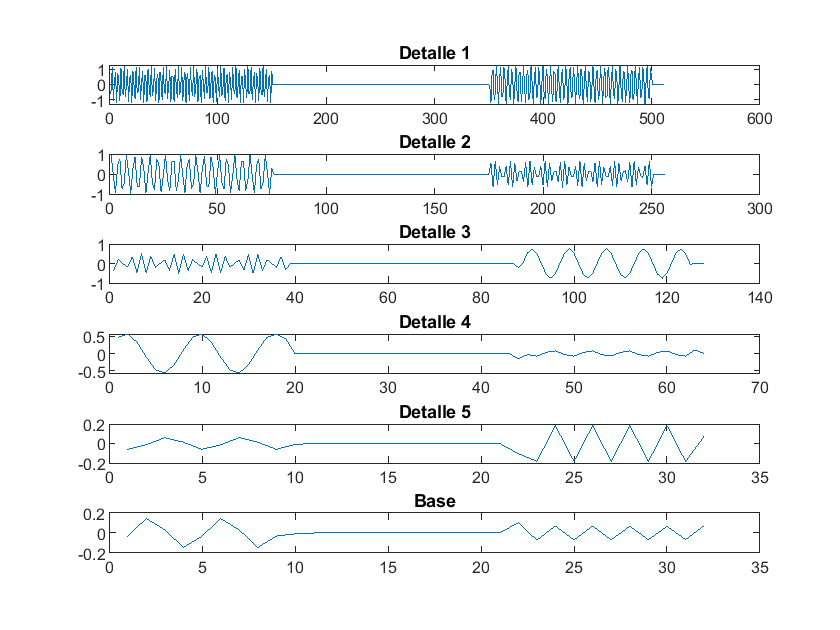

discreteCalculator = DiscreteWaveletTransform();

[details, base] = discreteCalculator.computeDWT(WaveletType.DAUBECHIES_1, signal', 5);

figure()
for i = 1:length(details)
    subplot(length(details) + 1,1,i)
    plot(details{i})
    title("Detalle "+string(i))
end

subplot(length(details) + 1,1,length(details) + 1)
plot(base)
title("Base")

Intenemos ahora reconstruir la señal con la inversa a ver si funciona

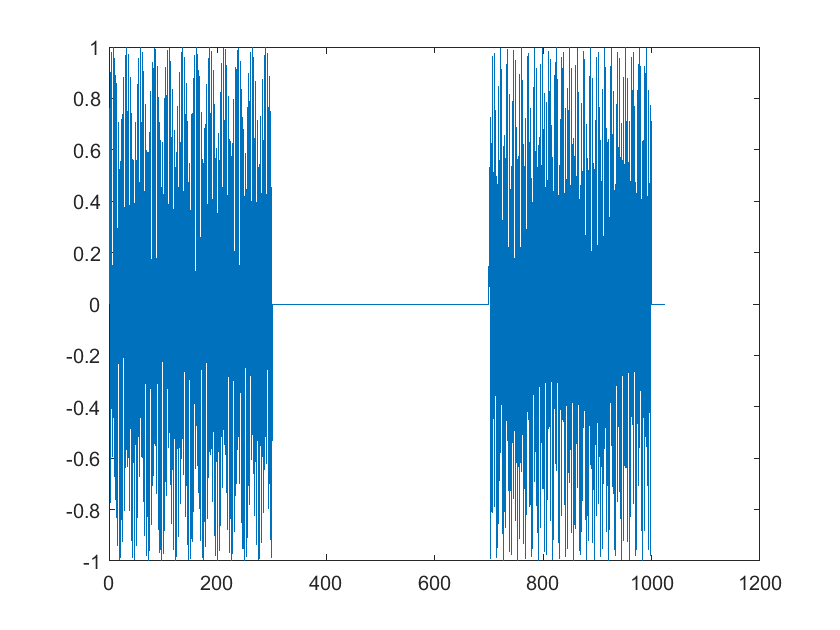

reconstructedSignal = discreteCalculator.reconstructDWT(WaveletType.DAUBECHIES_1, details, base);

figure()
title("Señal reconstruida")
plot(reconstructedSignal);

### Con Daubechies 4

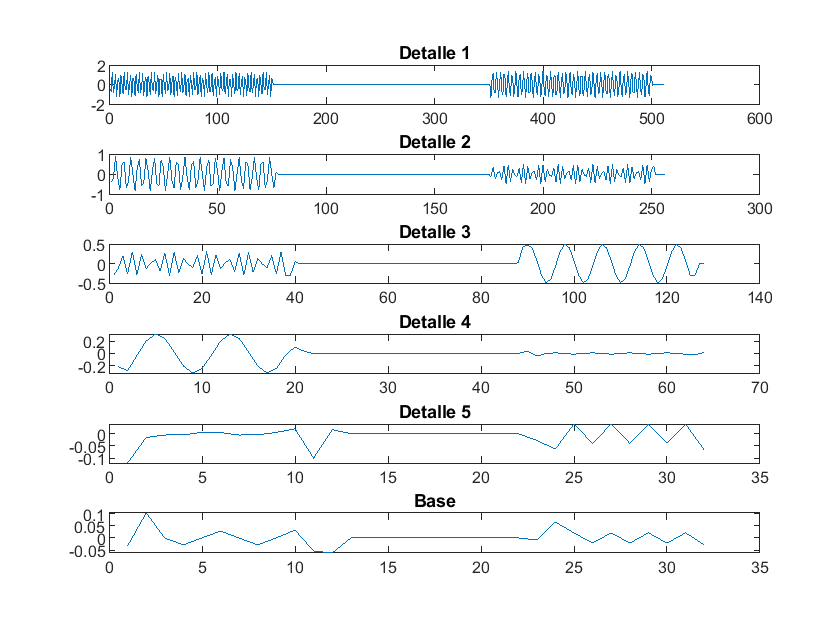

discreteCalculator = DiscreteWaveletTransform();

[details, base] = discreteCalculator.computeDWT(WaveletType.DAUBECHIES_4, signal', 5);

figure()
for i = 1:length(details)
    subplot(length(details) + 1,1,i)
    plot(details{i})
    title("Detalle "+string(i))
end

subplot(length(details) + 1,1,length(details) + 1)
plot(base)
title("Base")

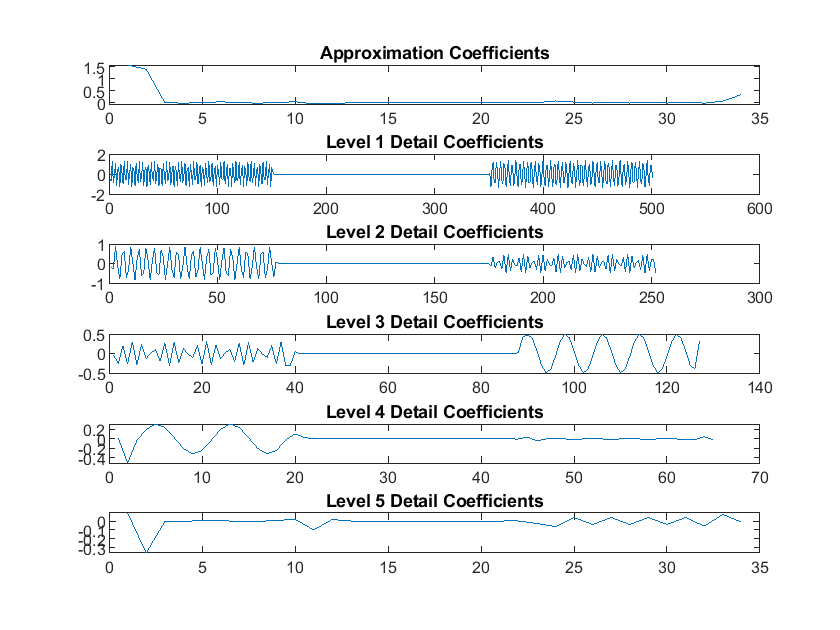

[c,l] = wavedec(signal,5,'db2');
approx = appcoef(c,l,'db2');
[cd1 cd2 cd3 cd4 cd5] = detcoef(c,l,[1 2 3 4 5]);
%Plot the coefficients.
figure()
subplot(6,1,1)
plot(approx)
title('Approximation Coefficients')
subplot(6,1,2)
plot(cd1)
title('Level 1 Detail Coefficients')
subplot(6,1,3)
plot(cd2)
title('Level 2 Detail Coefficients')
subplot(6,1,4)
plot(cd3)
title('Level 3 Detail Coefficients')
subplot(6,1,5)
plot(cd4)
title('Level 4 Detail Coefficients')
subplot(6,1,6)
plot(cd5)
title('Level 5 Detail Coefficients')

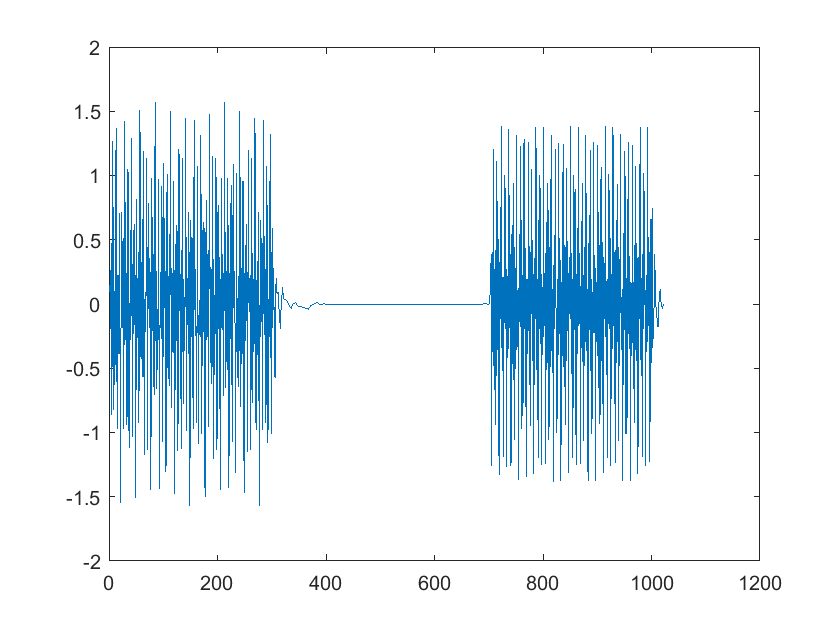

reconstructedSignal = discreteCalculator.reconstructDWT(WaveletType.DAUBECHIES_4, details, base);
figure()
title("Señal reconstruida")
plot(reconstructedSignal);

disp(norm(reconstructedSignal - signal))

  553.6819

